# Actividad 1.5 (Evaluación)

Víctor Manuel Vázquez Morales A01736352

clear
close all
clc

**Trayectoria 2: **

X = [0 a 5]

F(x) = 2*sen(x^2)

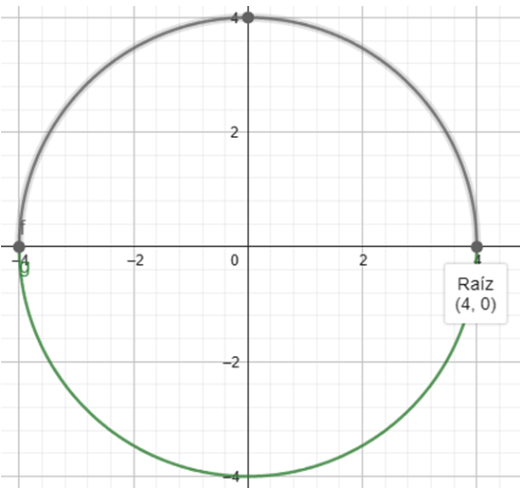

Iniciaremos la codificación de la trayectoria declarando el vector de tiempo en el que realizaremos las simulación, en dónde tf es el tiempo total de simulación y ts es el tiempo de muestro en segundos. 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Definimos el vector de tiempo

tf = 25;        % Tiempo final
ts = 0.1;       % Tiempo de muestreo en segundos (s)
t = 0:ts:tf;   % Vector de tiempo
N = length(t);  % Muestras


Ahora bien, considerando la imágen mostrada en la figura, iniciare la trayectoria posicionando al robot en la coordenada [0,4,0].

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = 4;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


Ahora bien, realizando algunas pruebas con las velocidades angulares y lineales pude identificar dos puntos importantes: 

- Para trazar una trayectoria circular, el robot debe contar tanto con velocidad lineal y angular constantes en todo momento.

- Existe una conexión entre el tamaño del círculo y la relación entre la velocidad lineal y angular. Es decir, mientras mayor sea la velocidad lineal en relación con la velocidad angular, mayor será el tamaño del circulo trazado y, además, el circulo que se forma cuando ambas velocidades son 1 es de 1 unidad de radio. 

Considerando lo anterior, se implemento la trayectoria declarando la velocidad lienal 4 veces mayor que la velocidad angular: 

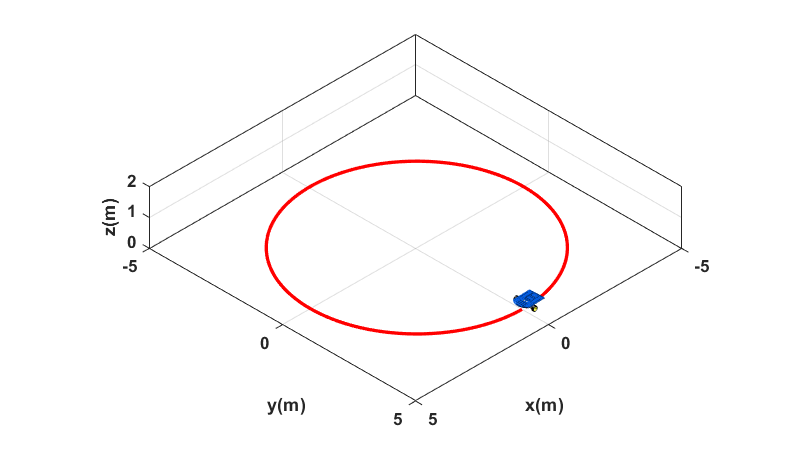

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = ones(1, N); %Velocidad lineal 
w = -1/4*ones(1, N); %La velocidad angular se declara de manera negativa ya que dada
% la posición inicial en theta debemos girar hacia la derecha


dt = floor(N/8); 

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-5 5 -5 5 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

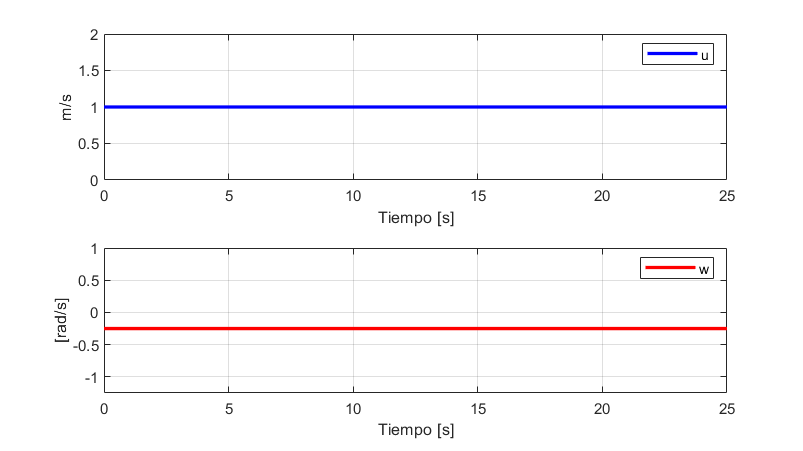


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');